clear;clc;

## Signal Generation

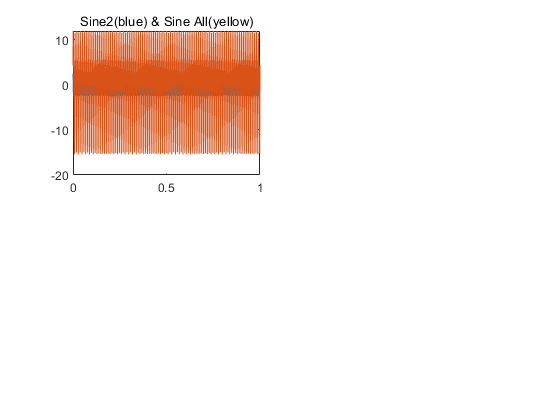

t_end = 1;                          % signal from 0 to 1s
% sampFreq = 1024;
sampIntrvl = 1/2048;
% samplFreq = 1/2*samplFreq;
timeVec = 0:sampIntrvl:t_end;       % Time samples
nSamples = length(timeVec);         % Number of samples

sig1 = 10*sin(2*pi*100*timeVec);
sig2 = 5*sin(2*pi*200*timeVec+pi/6);
sig3 = 2.5*sin(2*pi*300*timeVec+pi/4);
sigVec = sig1 + sig2 + sig3;
figure;
subplot(2,2,1)
plot(timeVec,sig3,timeVec,sigVec);
title('Sine2(blue) & Sine All(yellow)');

## FFT of signal

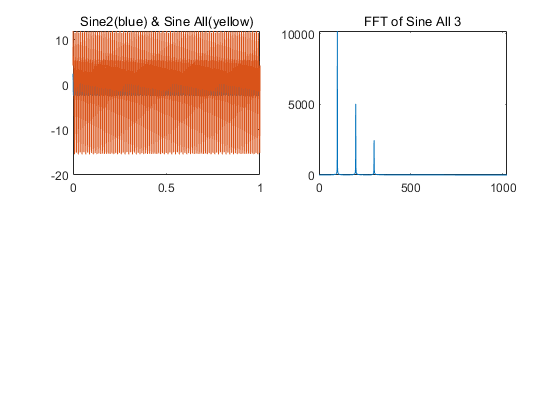

fftSig = fft(sigVec);

%dataLen = timeVec(end)-timeVec(1);
dataLen = t_end;                %Length of data 
kNyq = floor(nSamples/2)+1;%DFT sample corresponding to Nyquist frequency

posFreq = (0:(kNyq-1))*(1/dataLen); % Positive Fourier frequencies
fftSigPosi = fftSig(1:kNyq);        % Discard negative frequencies

subplot(2,2,2)
plot(posFreq,abs(fftSigPosi));      %Plot periodogram
title('FFT of Sine All 3');

%plot((0:nSamples-1)*(1/dataLen),abs(fftSig));  %Plot both +- periodogram

## Filtering Design

Remove frequencies above half the maximum frequency

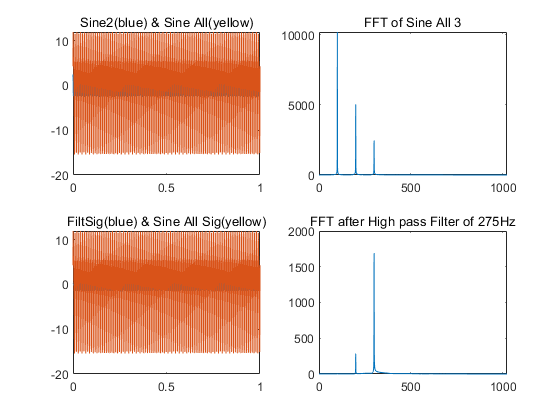

filtOrdr = 30;
%b = fir1(filtOrdr,125/(kNyq-1));   % Low pass Filter of 125Hz
%b = fir1(filtOrdr,[214/(kNyq-1), 215/(kNyq-1)]);% Band pass around 214.5Hz
b = fir1(filtOrdr,275/(kNyq-1),'high');    % High pass Filter of 275Hz

filtSig = fftfilt(b,sigVec);        % Apply filter

subplot(2,2,3)
plot(timeVec,filtSig,timeVec,sigVec);   
title('FiltSig(blue) & Sine All Sig(yellow)');
subplot(2,2,4)
%plot((0:nSamples-1)*(1/dataLen),abs(fft(filtSig)));
FiltFftSigPosi = fft(filtSig);
plot(posFreq,abs(FiltFftSigPosi((1:kNyq))));
title('FFT after High pass Filter of 275Hz');
print('Topic1-Lab5-3','-djpeg')

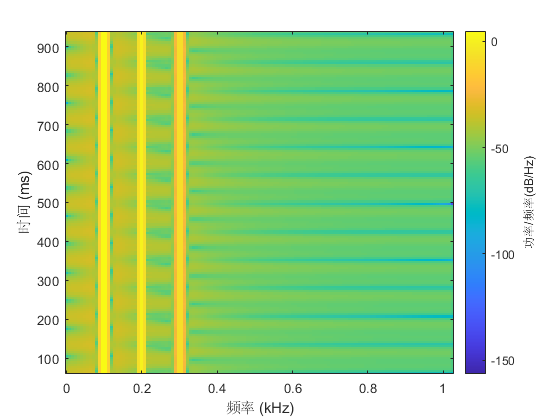


figure;
spectrogram(sigVec, 0.125/sampIntrvl,floor(0.12/sampIntrvl),[],nSamples);
print('Topic1-Lab6-Spec of 3 Sine','-djpeg')